clc
clear

dotQ=[10;10;10;10;10;10];
ke=100;
kp=10;
%initial value
Q=[0;0;0;0;0;0];
Qa=[0;0;0;0;0;0];
q=[0;0;0;0;0;0];
Rinf=300;
r=0.3;
lambda=0;
%dt
elasticdt=0.005;
plasticdt=0.005/100;
dotlam=0;

Rela=Rinf*sqrt(1-r*exp(-2*lambda*kp/Rinf));
if norm(Q(:,1))-Rela>0
else
    iflag=0;
end

for i=1:40000
    if iflag==0
        q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
        Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
        Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
        lambda(:,i+1)= lambda(:,i);
        dotlam(:,i+1)= dotlam(:,i);
        Rela(:,i+1)= Rela(:,i);
        if norm(Q(:,i+1))-Rela(:,i+1)>0
            if Q(:,i+1)'*dotQ<0
                iflag=0;
                q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
                Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
                Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
                lambda(:,i+1)=lambda(:,i);
                dotlam(:,i+1)= dotlam(:,i);
                Rela(:,i+1)= Rela(:,i);
            else
                iflag=1;
                i+1
                syms dt
                f=Q(:,i)+dotQ*dt;
                f1=norm(f)-Rela(:,i);
                dt1=solve(f1,dt);
                dt=double(dt1);
                q(:,i+1)=q(:,i)+(dotQ/ke)*dt;
                Q(:,i+1)=Q(:,i)+dotQ*dt;%Qton
                Qa(:,i+1)=Qa(:,i)+dotQ*dt;
                lambda(:,i+1)=lambda(:,i);
                dotlam(:,i+1)= dotlam(:,i);
                Rela(:,i+1)= Rela(:,i);
                ik=1;
            end
        end
    end
    if iflag==1 && ik==0
        q(:,i+1)=q(:,i)+(Qa(:,i)'*dotQ*Qa(:,i)/(kp*Rinf*Rinf)+dotQ/ke)*plasticdt;
        Q(:,i+1)=Q(:,i)+dotQ*plasticdt;
        Qa(:,i+1)=Qa(:,i)+(-Qa(:,i)'*dotQ*Qa(:,i)/(Rinf*Rinf)+dotQ)*plasticdt;
        dotlam(:,i+1)=Qa(:,i+1)'*dotQ/(kp*Rinf);
        lambda(:,i+1)=lambda(:,i)+(dotlam(:,i+1)*plasticdt);
        Rela(:,i+1)=Rinf*sqrt(1-r*exp(-2*lambda(:,i+1)*kp/Rinf));
        if Q(:,i+1)'*dotQ<0
            iflag=0;
            q(:,i+1)=q(:,i)+(dotQ/ke)*elasticdt;
            Q(:,i+1)=Q(:,i)+dotQ*elasticdt;
            Qa(:,i+1)=Qa(:,i)+dotQ*elasticdt;
            lambda(:,i+1)=lambda(:,i);
            dotlam(:,i+1)= dotlam(:,i);
            Rela(:,i+1)= Rela(:,i);
        end
    end
    ik=0;
end

ans = 2051

abc=[];
for i=1:size(Rela,2)
    abc(:,i)=norm(Qa(:,i))-Rela(:,i);
end

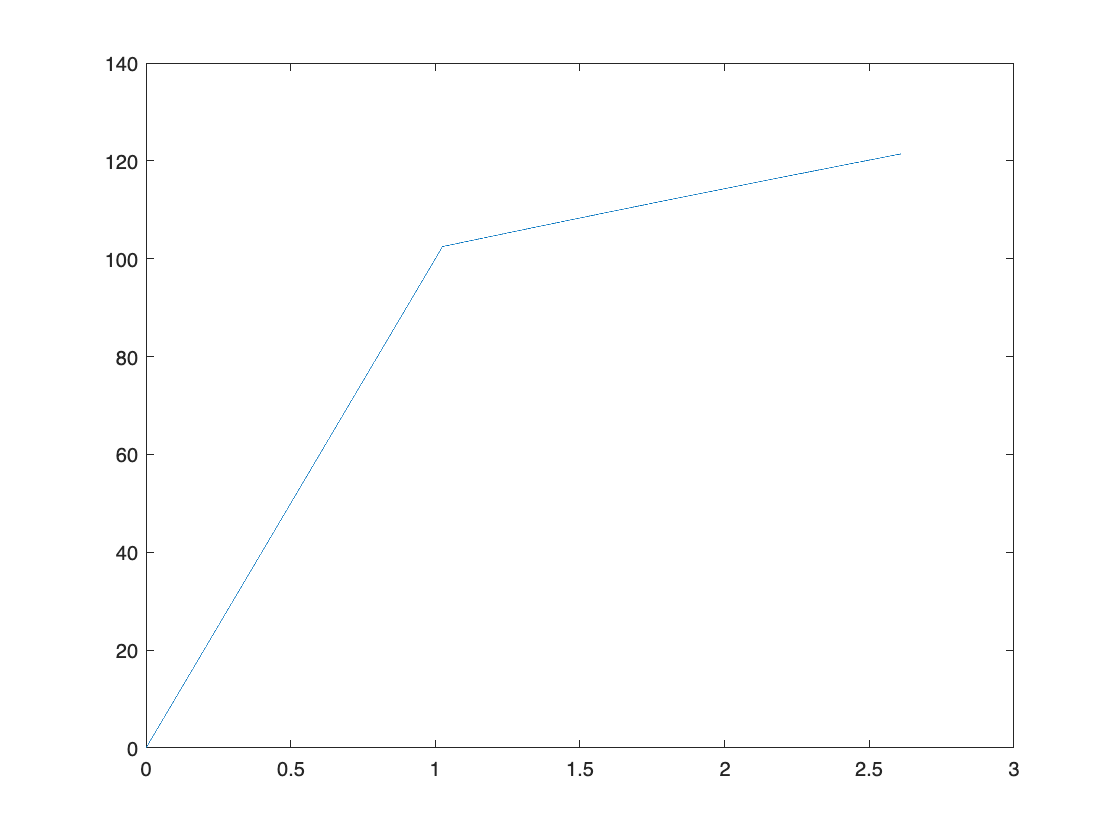

plot(q(1,:),Q(1,:))